# Nyquist Stability Criterion

- Derive Nyquist plots from Transfer Functions $G(s)$ where $s = \sigma + j\omega$

s = tf('s');
G = 1/((s+2)*(s+4)*(s+6))

G =
 
             1
  ------------------------
  s^3 + 12 s^2 + 44 s + 48
 
Continuous-time transfer function.



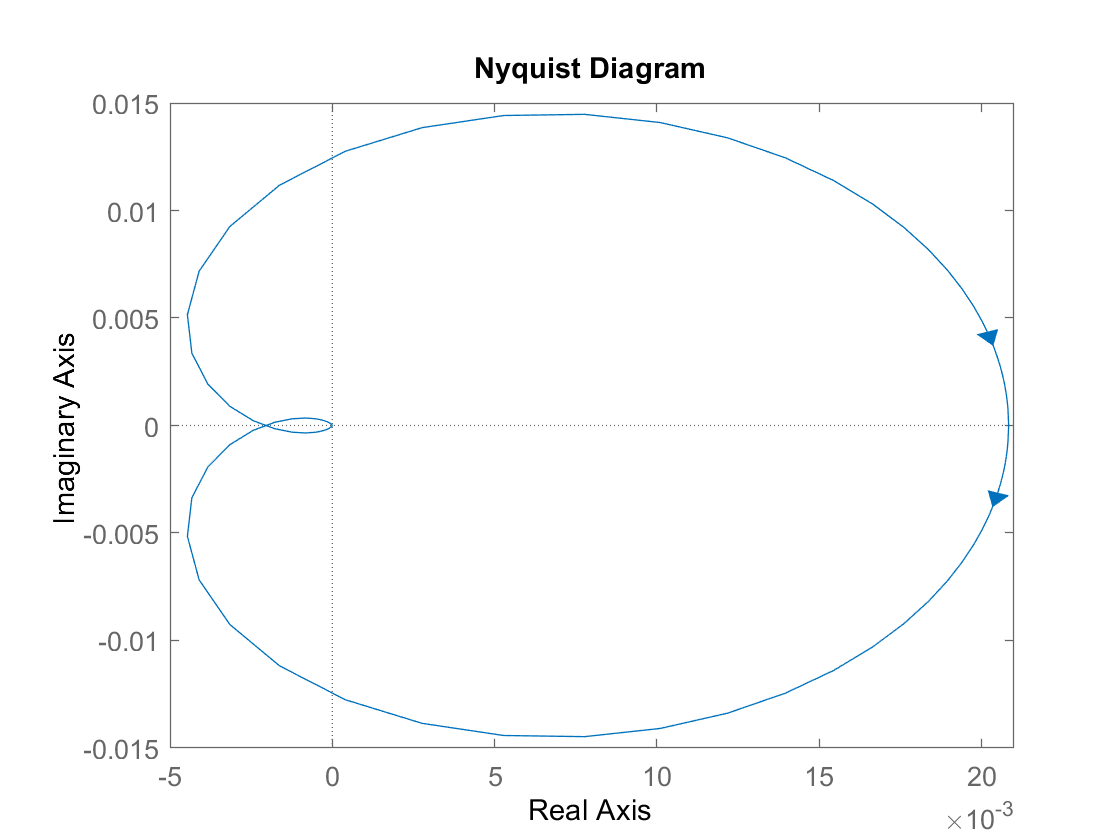

figure, nyquist(G), xlim([-0.005 .021])

syms s w
G = 1/((s+2)*(s+4)*(s+6))

$$G = \frac{1}{\left(s+2\right)\,\left(s+4\right)\,\left(s+6\right)}$$

G_w = subs(G,s,j*w)

$$G\_w = \frac{1}{\left(2+w\,\mathrm{i}\right)\,\left(4+w\,\mathrm{i}\right)\,\left(6+w\,\mathrm{i}\right)}$$

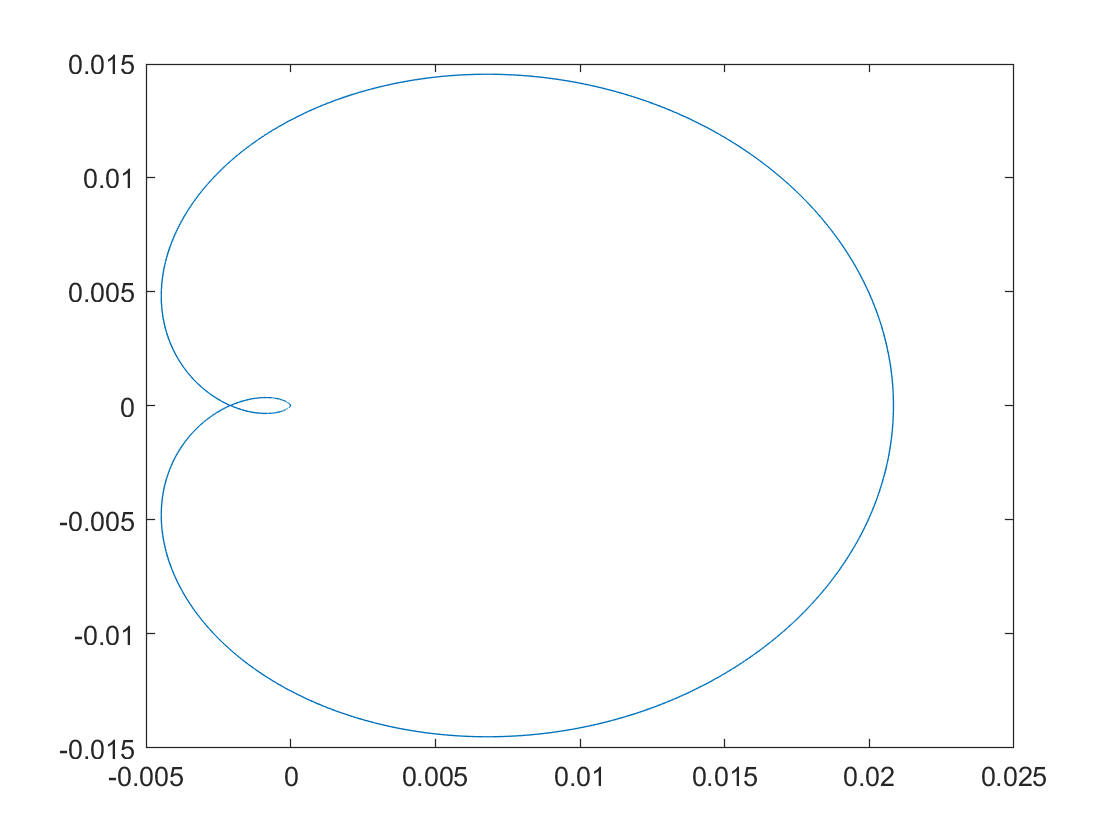

W = -100:.01:100; 
Nyq = eval(subs(G_w,w,W));
x = real(Nyq);
y = imag(Nyq);
figure, plot(x,y)

Now we can solve for the Gain margin: 

Want to find the points when our imaginary values change sign

tmp = sign(y);
d = diff(tmp);
indexes = find(d ~= 0)

indexes =         9337       10000       10001       10664


points = W(indexes), a = points(4)

points =    -6.6400   -0.0100         0    6.6300


a = 6.6300

GainFactor = 1/abs(x(indexes(4)))

GainFactor = 479.4830

Thus our Gain Factor for this transfer function is about 480

## Assessing Gain and Phase Margins

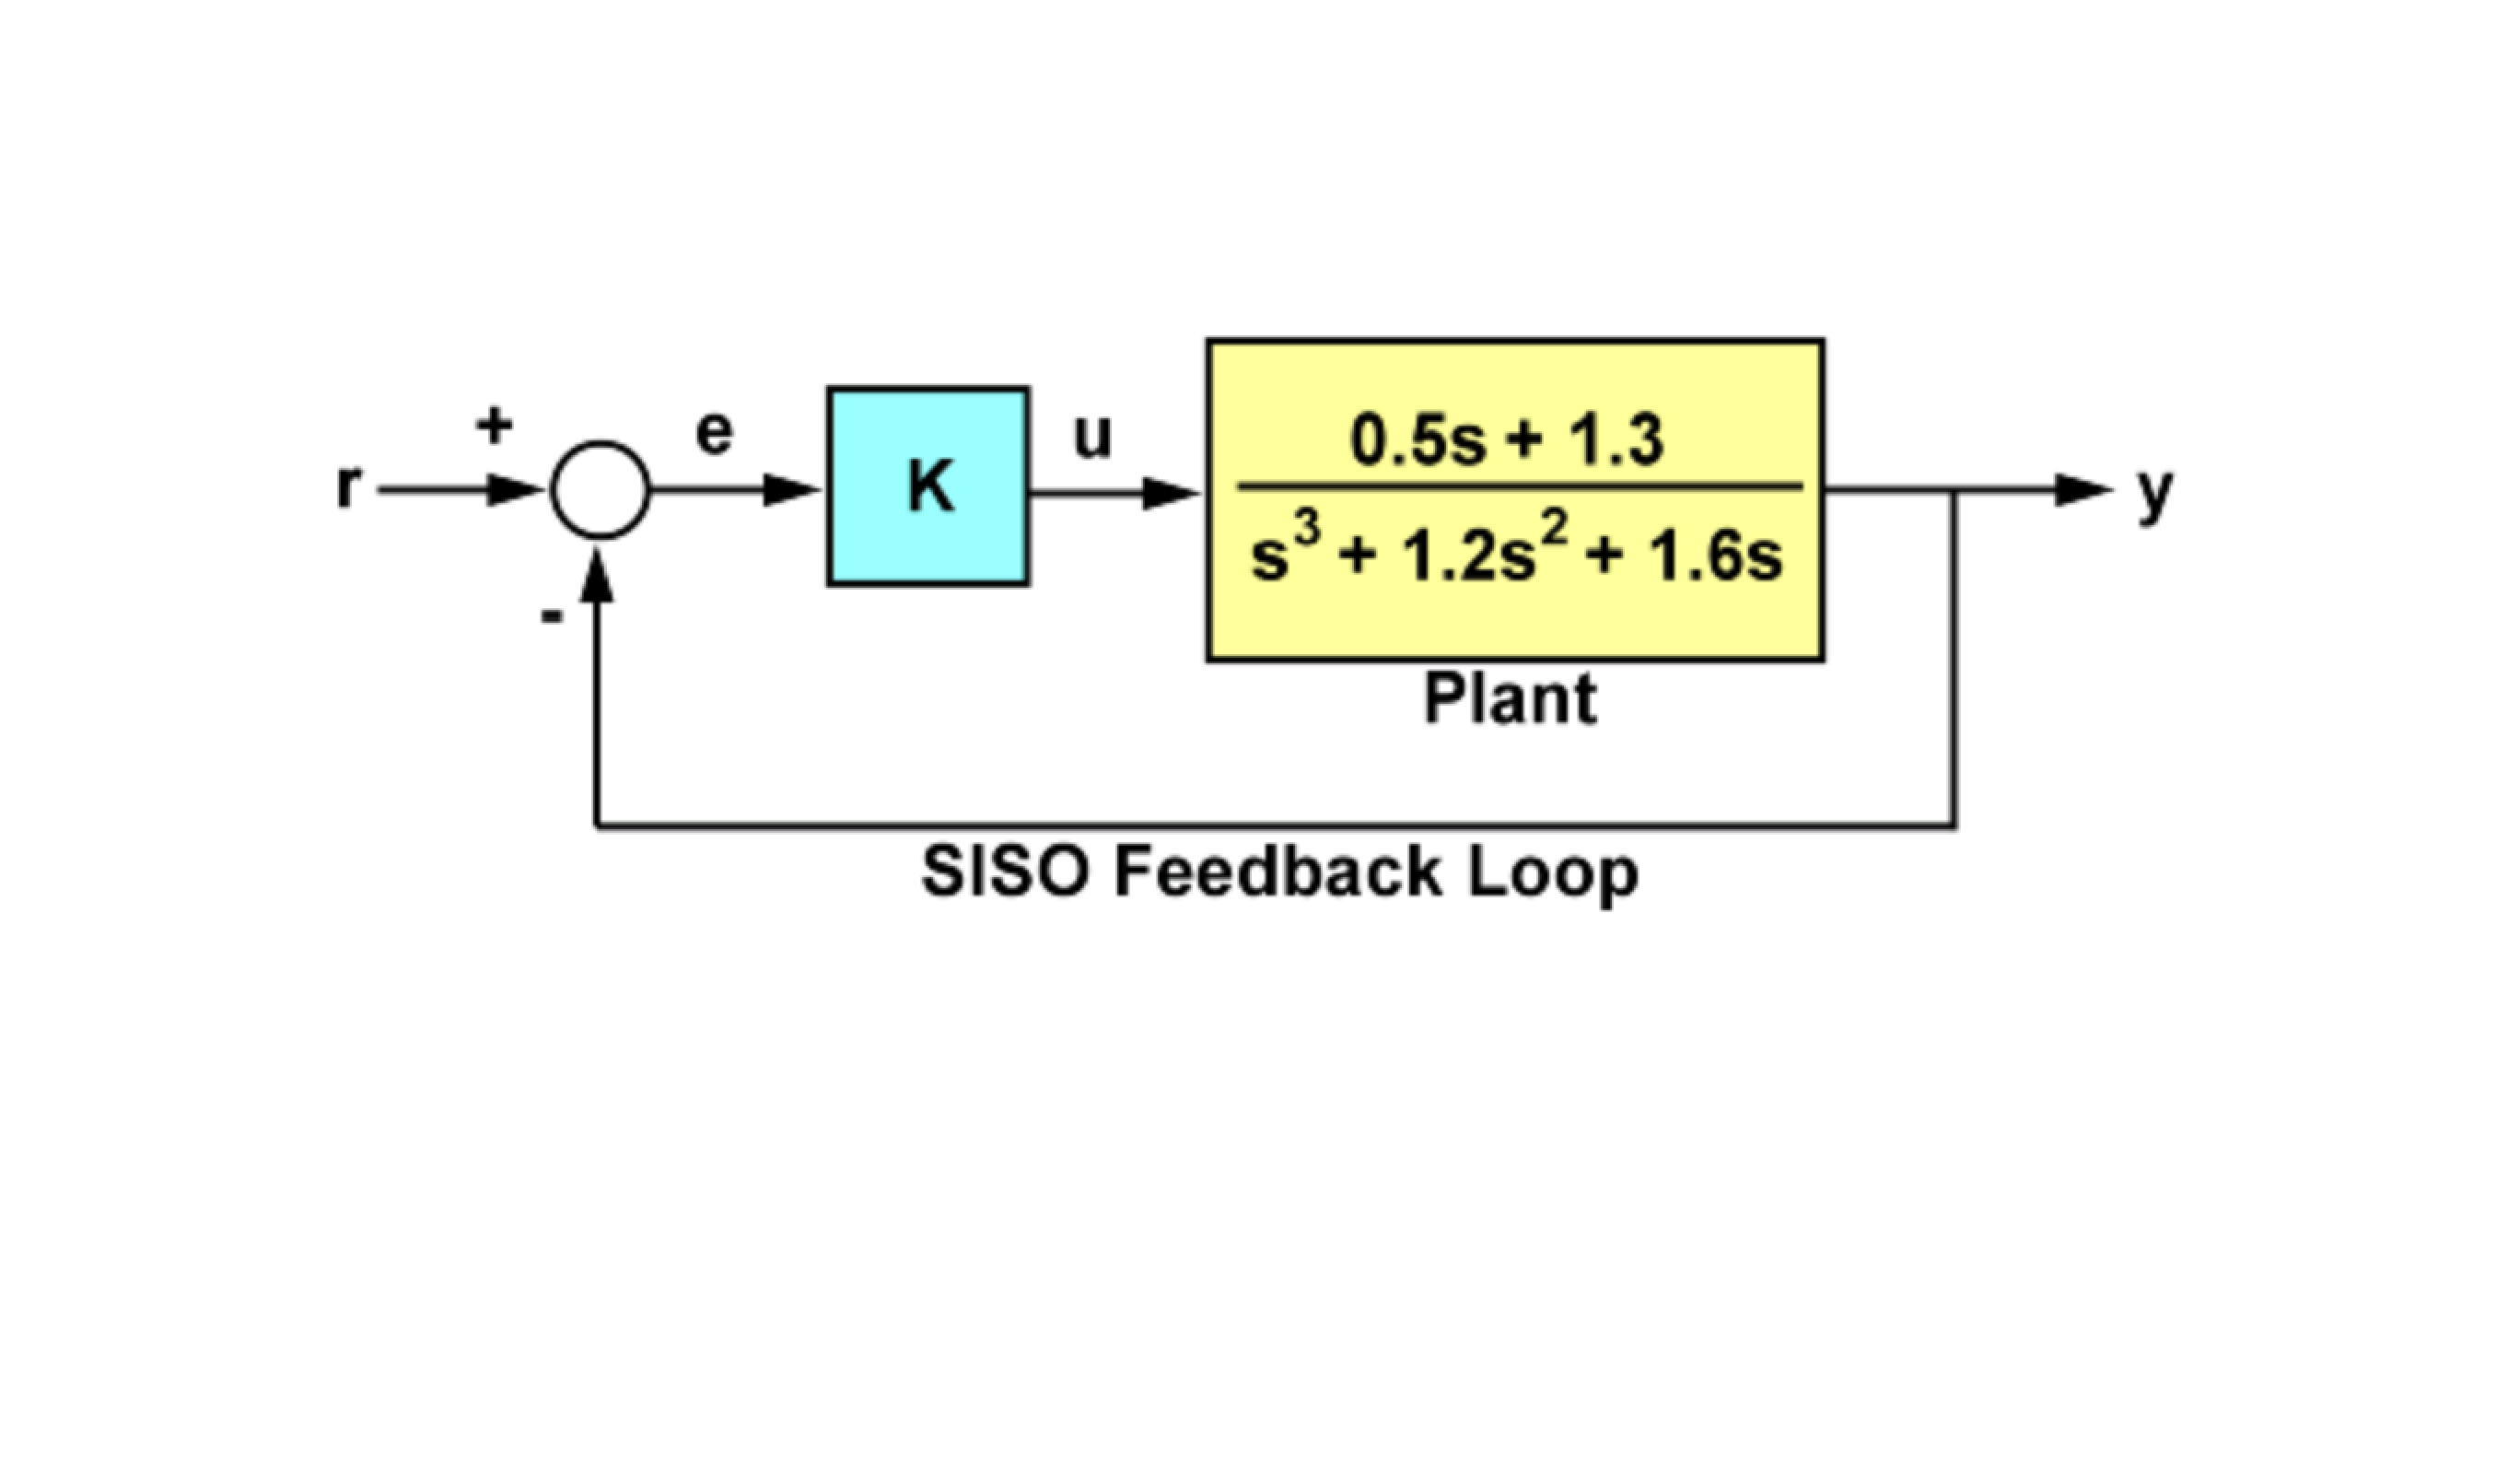

f = imread('StabilityExample.png'); imshow(f)

G = tf([0.5 1.3],[1 1.2 1.6 0])

G =
 
       0.5 s + 1.3
  ---------------------
  s^3 + 1.2 s^2 + 1.6 s
 
Continuous-time transfer function.



T = feedback(G,1)

T =
 
          0.5 s + 1.3
  ---------------------------
  s^3 + 1.2 s^2 + 2.1 s + 1.3
 
Continuous-time transfer function.



p = pole(T)

p =   -0.2305 + 1.3062i
  -0.2305 - 1.3062i
  -0.7389 + 0.0000i


p1mag = abs(p(1)), p1pha = angle(p(1))*(180/pi)

p1mag = 1.3264

p1pha = 100.0092

p2mag = abs(p(2)), p2pha = angle(p(2))*(180/pi)

p2mag = 1.3264

p2pha = -100.0092

p3mag = abs(p(3)), p3pha = angle(p(3))*(180/pi)

p3mag = 0.7389

p3pha = 180

Root Locus of G:

rlocus(G)

Using the Root Locus, we want to assess how much the gain can change before stability to the system is lost

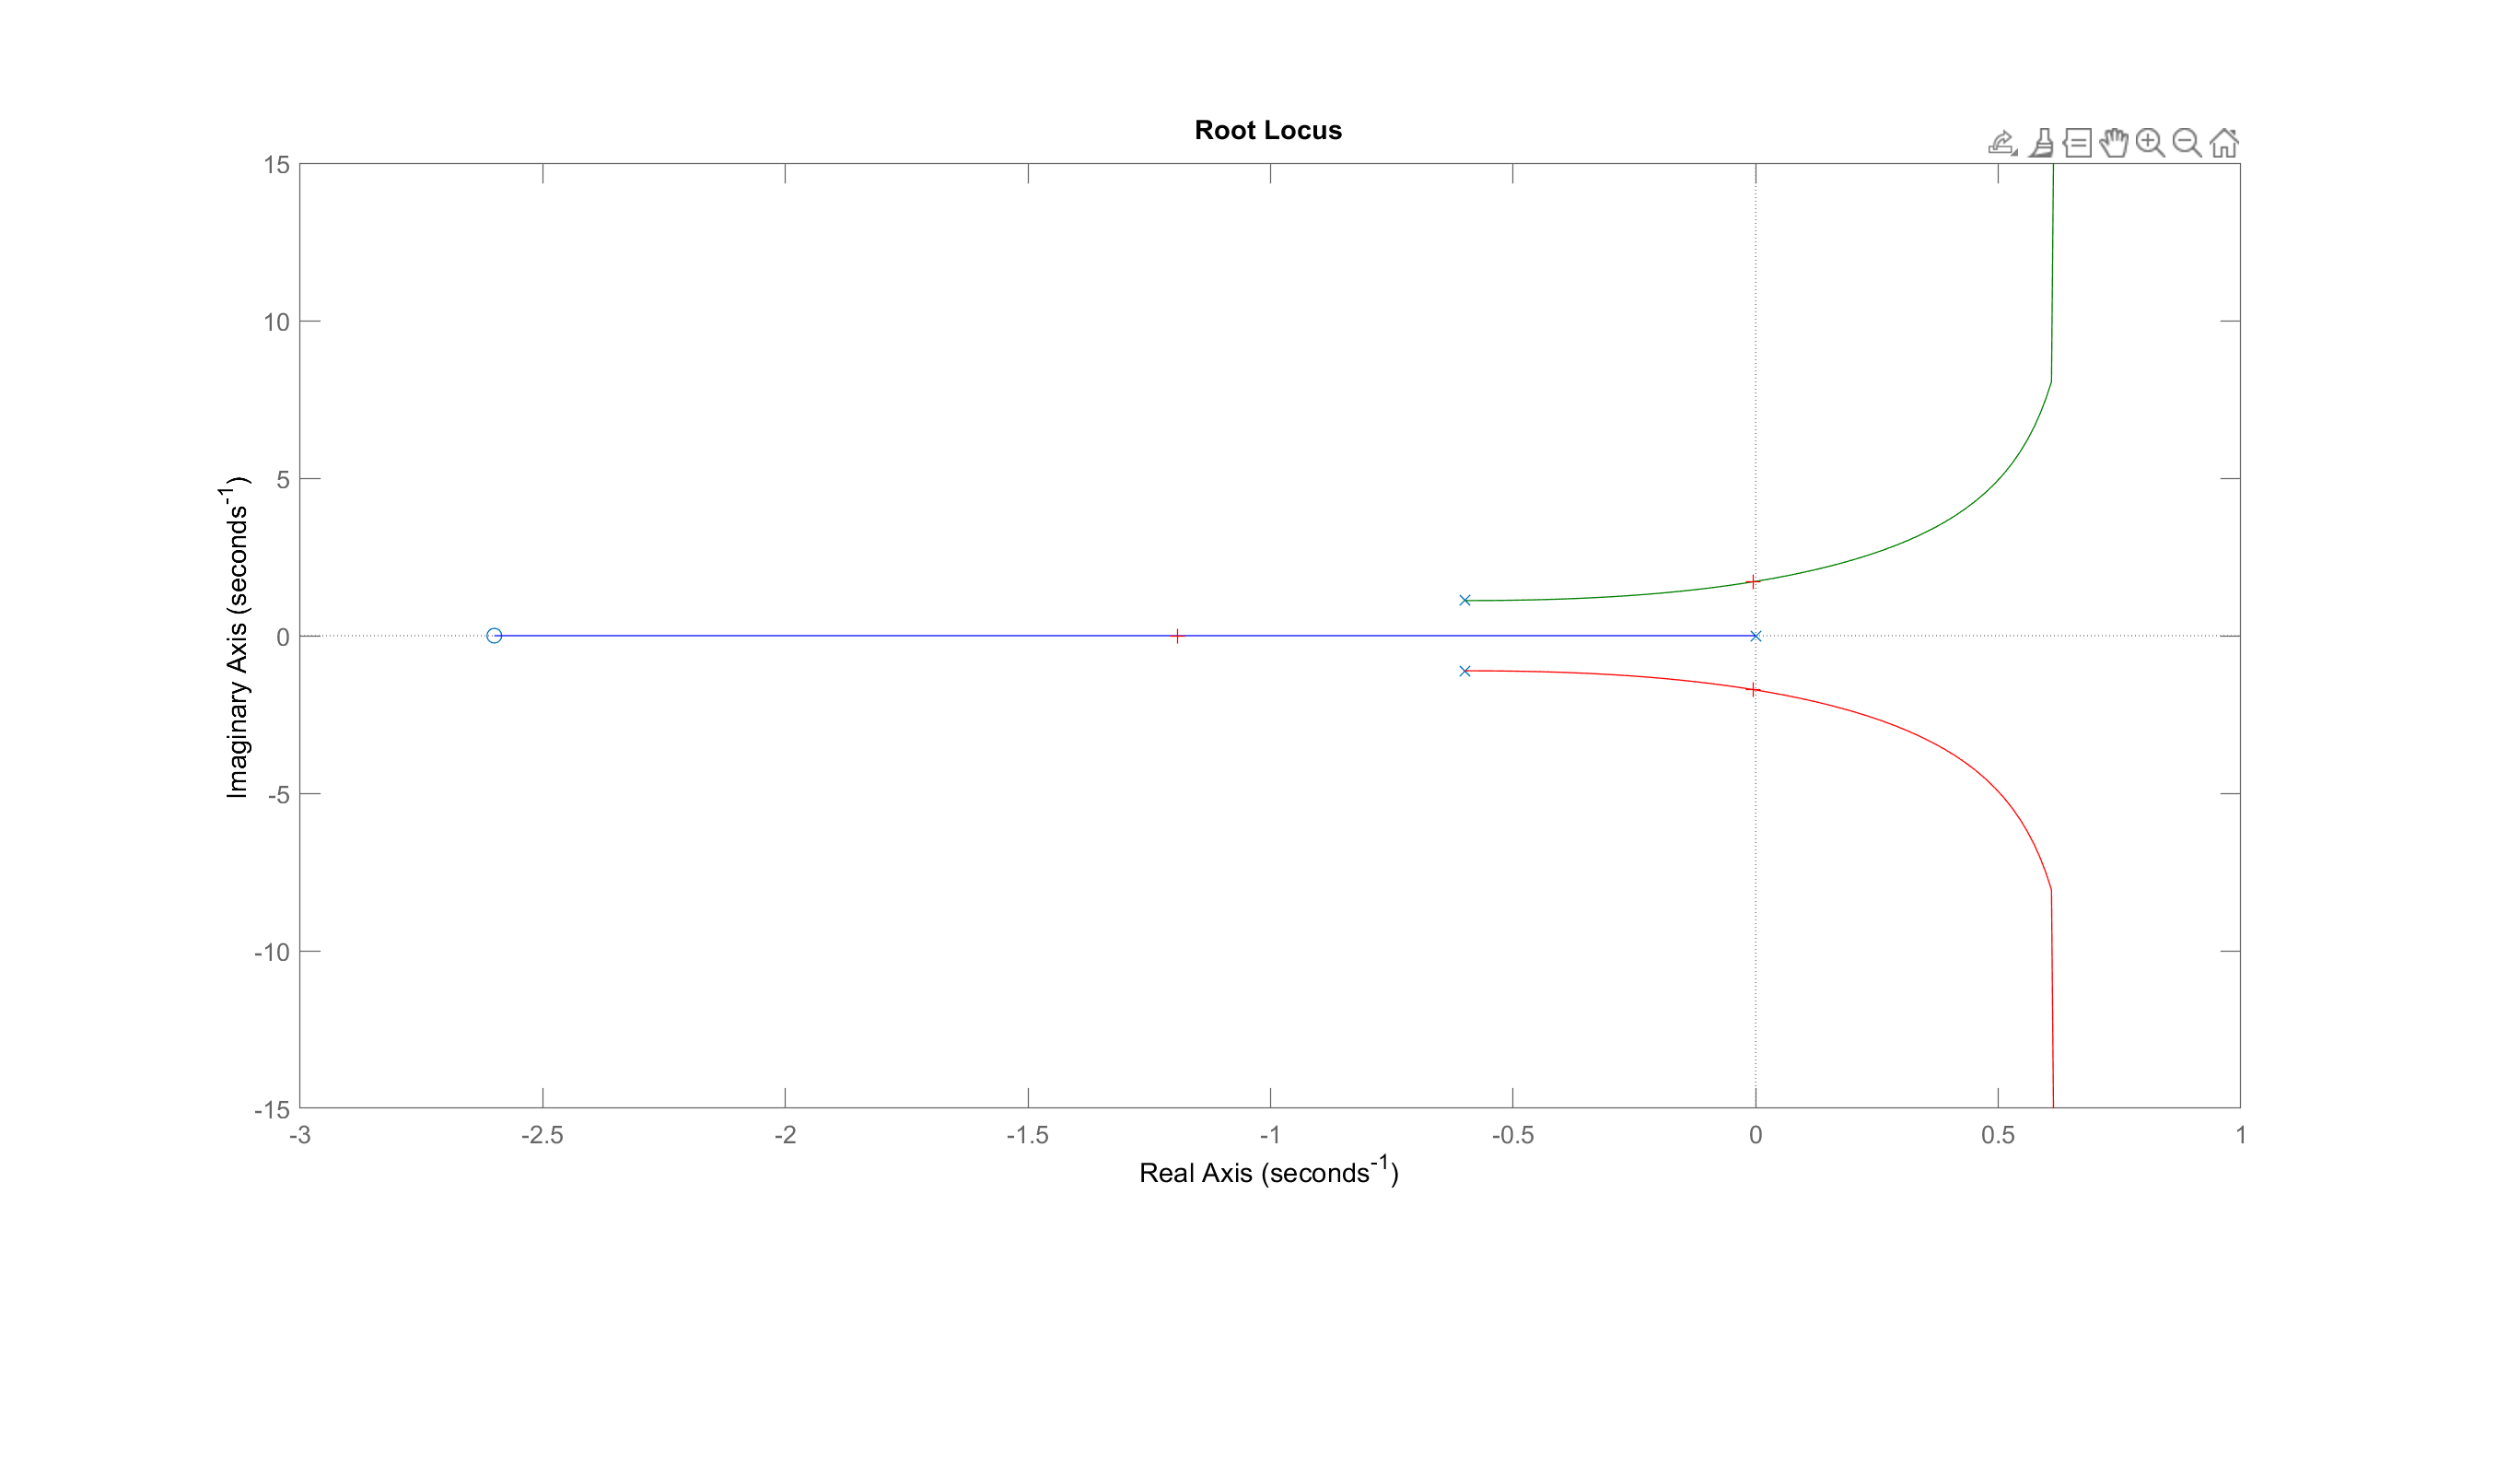

Select a point in the graphics window


selected_point = 0.0005 + 1.7105i

k = 2.6869

poles =   -0.0045 + 1.7125i
  -0.0045 - 1.7125i
  -1.1910 + 0.0000i


[k,poles] = rlocfind(G)

Clicking on the imaginary axis of the graph we see that when $k = 2.7$ is when the system becomes unstable.

Thus our gain can be within the range of $0 < k < 2.7 $

### Gain and Phase Margins

The phase margin measures how much phase variation is needed at the gain crossover frequency to lose stability. Similarly, the gain margin measures what relative gain variation is needed at the gain crossover frequency to lose stability. Together, these two numbers give an estimate of the "safety margin" for closed-loop stability. The smaller the stability margins, the more fragile stability is

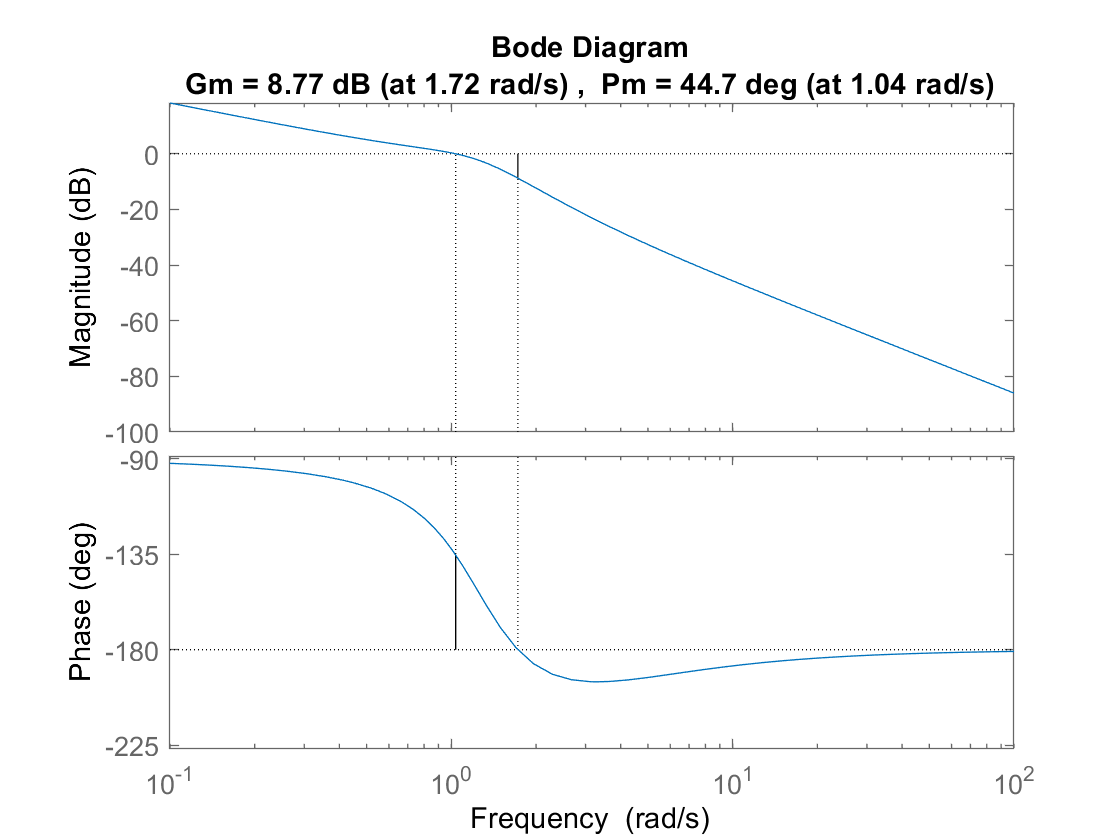

bode(G), grid, margin(G)